Definizione del **numeratore** e del **denominatore** della **FdT**.

num = 100;
den = conv(conv([1 1],[1 1]),[1 1]);

% num = 1;
% den = [1 0];

sys = tf(num,den)


sys =
 
           100
  ---------------------
  s^3 + 3 s^2 + 3 s + 1
 
Continuous-time transfer function.
Model Properties


Calcolo dei **poli** del sistema dinamico.

pole(sys)

ans =   -1.0000 + 0.0000i
  -1.0000 - 0.0000i
  -1.0000 + 0.0000i


Tracciamento del **diagramma di Bode**.

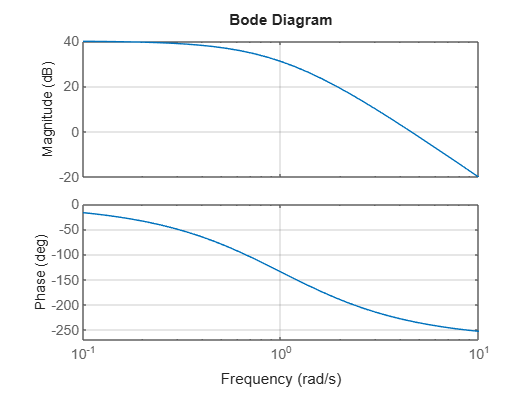

bode(sys);
grid on

Calcolo del **Margine di Guadagno** e** di Fase.**

- **Margine di Guadagno**: calcolato in 𝜔𝜋, che è la pulsazione in corrispondenza della quale la fase della funzione di trasferimento ad anello aperto 𝐹(𝑠) calcolata in 𝑗𝜔 è pari a −180°.

- **Margine di Fase**: calcolato in 𝜔𝜋, che è la pulsazione in corrispondenza della quale il modulo della funzione di trasferimento ad anello aperto 𝐹(𝑠) calcolata in 𝑗𝜔 è pari ad 1 (a 0 se analizziato in Decibel – dB).

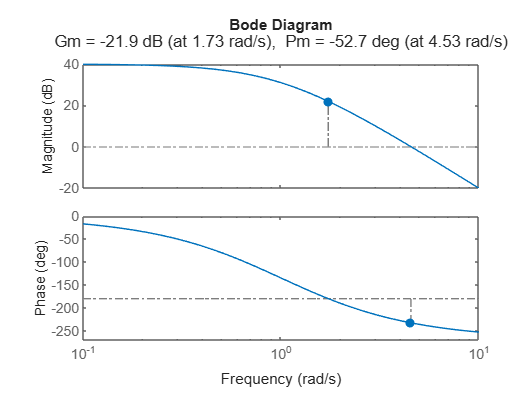

margin(sys)

grid on